min = 0

min = 0

max = 2*pi;

nt = 500;
xt = min:(max-min)/nt:max;
yt = sin(xt);

nc = 55;

xsin = min:(max-min)/(nc-1):max

xsin =          0    0.1164    0.2327    0.3491    0.4654    0.5818    0.6981    0.8145    0.9308    1.0472    1.1636    1.2799    1.3963    1.5126    1.6290    1.7453    1.8617    1.9780    2.0944    2.2108    2.3271    2.4435    2.5598    2.6762    2.7925    2.9089    3.0252    3.1416    3.2579    3.3743    3.4907    3.6070    3.7234    3.8397    3.9561    4.0724    4.1888    4.3051    4.4215    4.5379    4.6542    4.7706    4.8869    5.0033    5.1196    5.2360    5.3523    5.4687    5.5851    5.7014


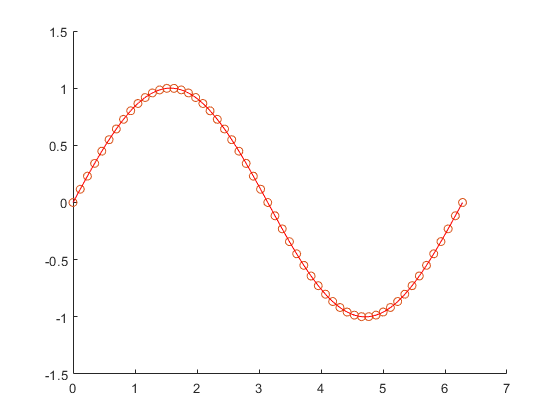

ysin = sin(xsin);

hold on 
plot(xt, yt,  "LineStyle","-", "Color", [0 0 1])
plot(xsin, ysin,  "LineStyle","none", "Marker","o")

resultat = zeros(1, nt);

for k = 1:nt+1
    accSomme = 0;
    for i = 1:nc
        accMul = 1;
        for j = 1:nc
            if(i == j)
                continue;
            end
            accMul = accMul * ((xt(k) - xsin(j)) / (xsin(i) - xsin(j)));
        end
        accSomme = accSomme  + accMul * ysin(i);
    end
    resultat(k) = accSomme;
end

plot(xt, resultat,  "LineStyle","-", "Color", [1 0 0])